Estimate impulse response

recObj = audiorecorder;
disp('start receiving.');
recordblocking(recObj, 3);

start receiving.


disp('end receiving');
% h_received = getaudiodata(recObj);

end receiving


plot(h_received);

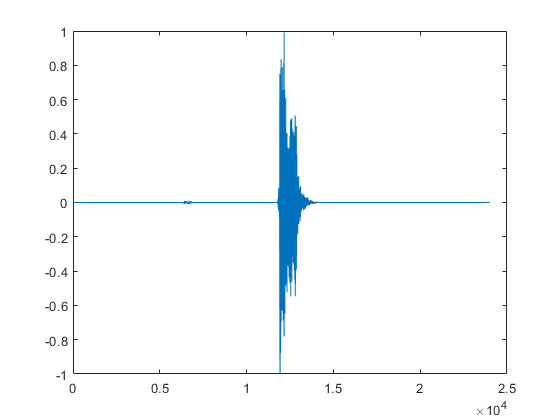

h_xcorr = xcorr(h_received, n);

plot(h_xcorr)

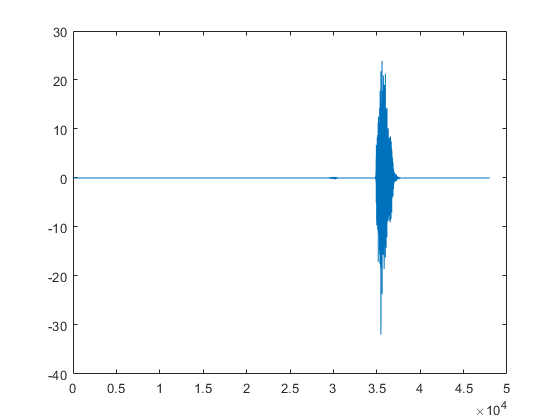

for i=1:size(h_xcorr)
    if h_xcorr(i) > 1

        break
    end
end
for j=size(h_xcorr):-1:1
    if h_xcorr(j) > 1
        break
    end
end
h = h_xcorr(i:j)
plot(h)

Text decoding

recObj = audiorecorder;

h =     1.2131
    1.2010
   -0.0725
    0.3224
   -0.1037
   -1.6572
   -2.5563
   -2.2311
   -0.4965
    1.6319


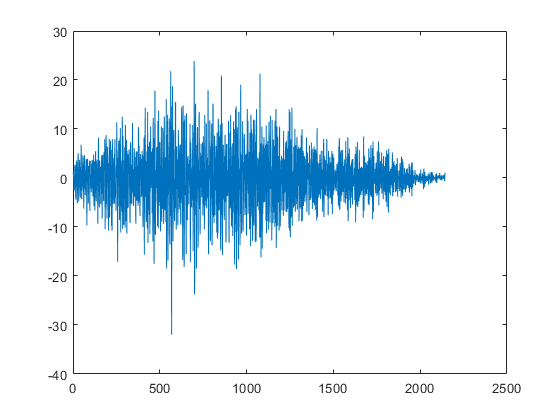

disp('start receiving.');

start receiving.


end receiving


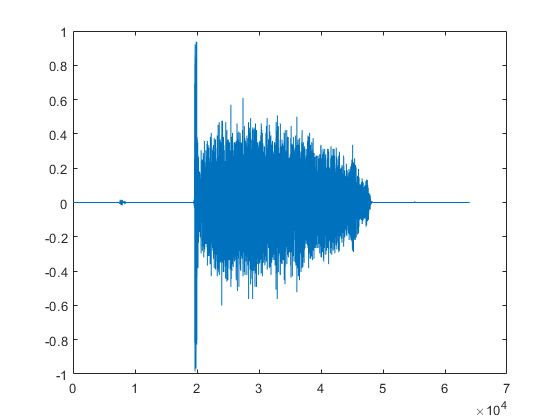

recordblocking(recObj, 8);
disp('end receiving');
y = getaudiodata(recObj);
plot(y);

n: input white noise

h_received: received response from white noise input

h: estimated channel response

y: received response from encoded text message